# Computer Assignment 4 - Signals & Systems - Dr  Akhavan

### Question 1

clc, clearvars, close all;

#### 1 - 1) Creating mapset

Nch = 32; 
mapset = cell(2,Nch); 
Alphabet ='abcdefghijklmnopqrstuvwxyz .,!";'; 
for i = 1:Nch 
    mapset{1,i}=Alphabet(i); 
    mapset{2,i}=dec2bin(i-1,5); 
end

#### 1 - 2)

#### 1 - 3)

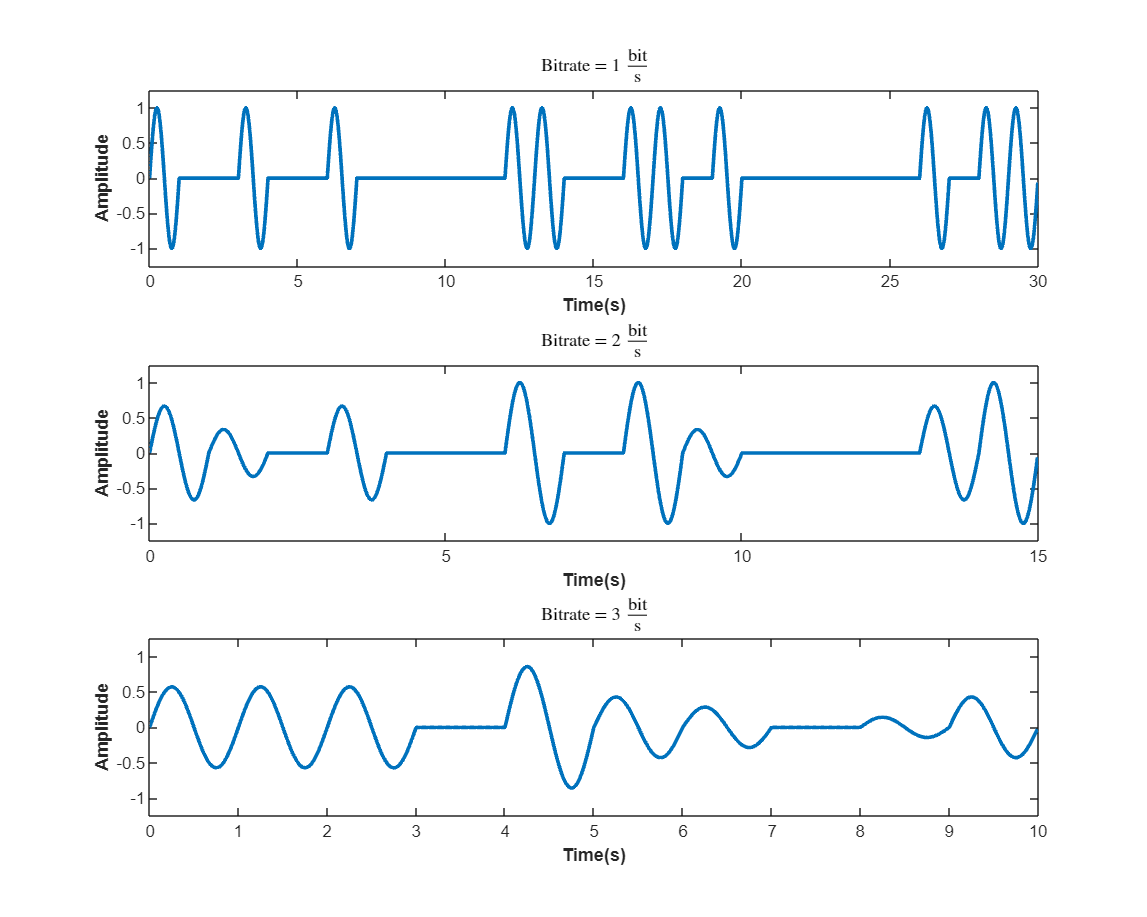

message = 'signal';
fs = 100;
codedMessage = cell(1, 3);
figure('Position', [0,0,1000,800]);
for bitrate = 1:3
    codedMessage{bitrate} = coding_amp(message, bitrate, mapset);
    t = 0:(1/fs):(length(codedMessage{bitrate})/fs)-(1/fs);
    subplot(3, 1, bitrate);
    plot(t,codedMessage{bitrate}, 'LineWidth', 2)
    title("Bitrate = " + bitrate + " $\frac{\mathrm{bit}}{\mathrm{s}}$",'Interpreter','latex')
    xlabel("Time(s)", FontName="Arial", FontWeight="bold"); ylabel("Amplitude", FontName="Arial", FontWeight="bold");
    ylim([-1.25, 1.25]);
end

#### 1 - 4)

for bitrate = 1:3
    decodedMessage = decoding_amp(codedMessage{bitrate}, bitrate, mapset);
    fprintf ('Bitrate: %d Decoded Message: %s\n', bitrate, decodedMessage)
end

Bitrate: 1 Decoded Message: signal
Bitrate: 2 Decoded Message: signal
Bitrate: 3 Decoded Message: signal


#### 1 - 5)

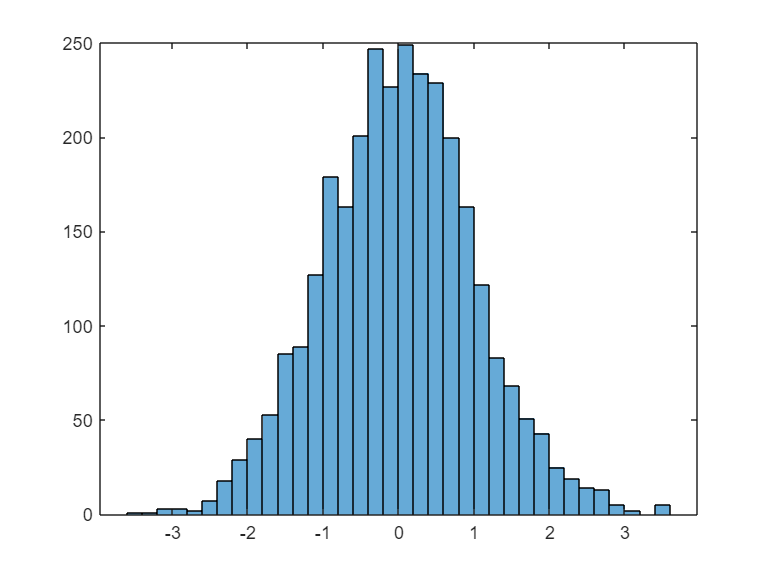

noise = randn(1, 3000);
figure;
histogram(noise);

Mean = mean(noise)

Mean = 0.0142

variance = var(noise)

variance = 1.0025

#### 1 - 6)

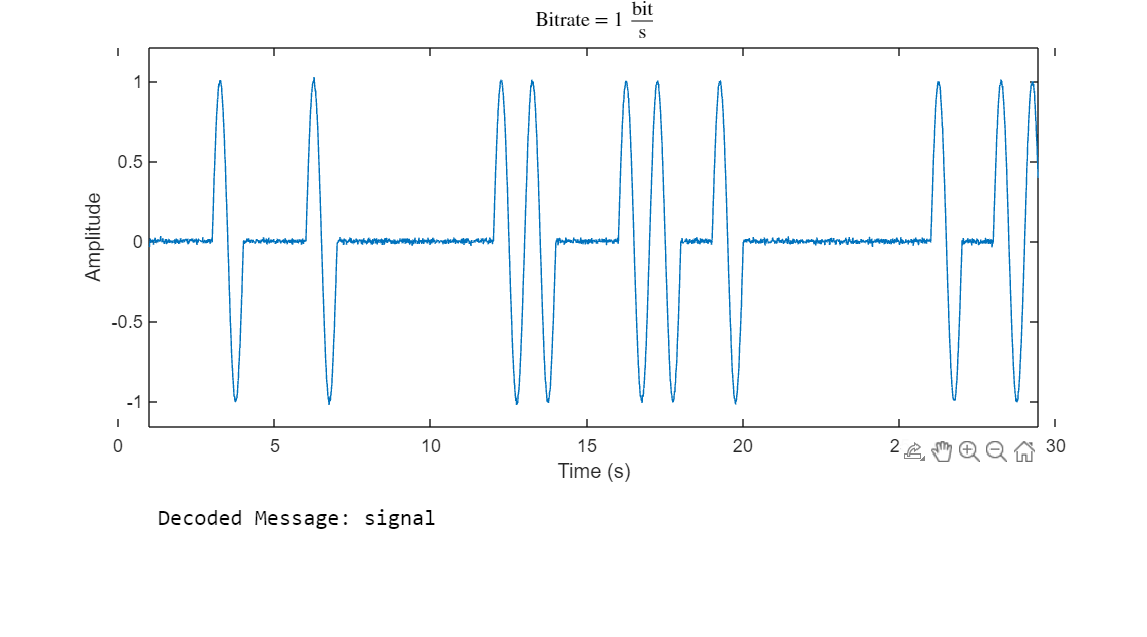

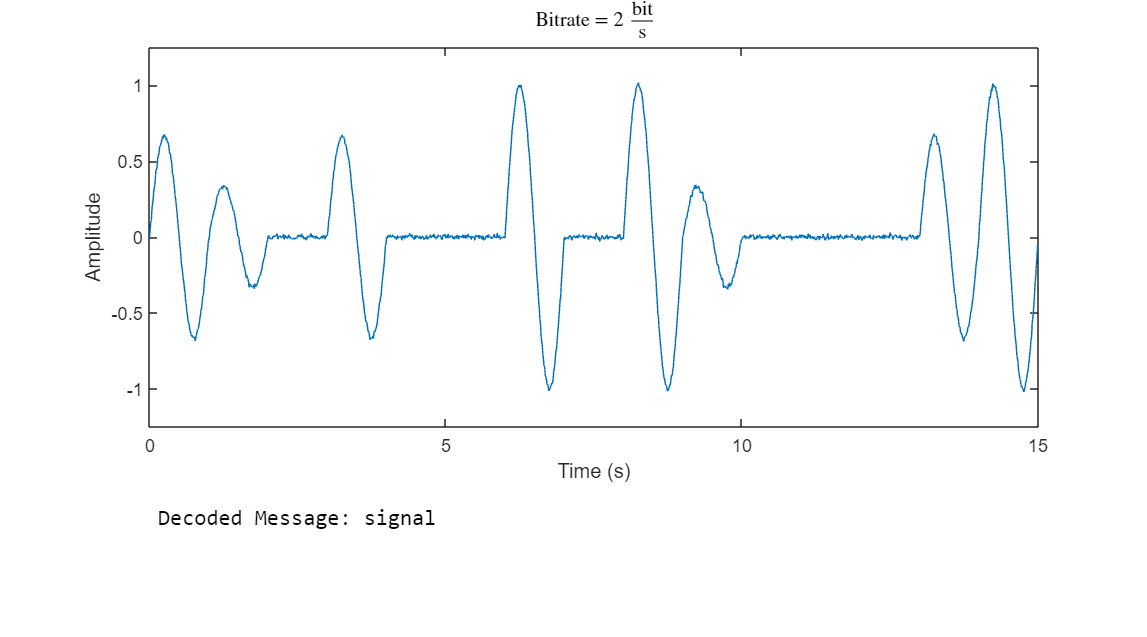

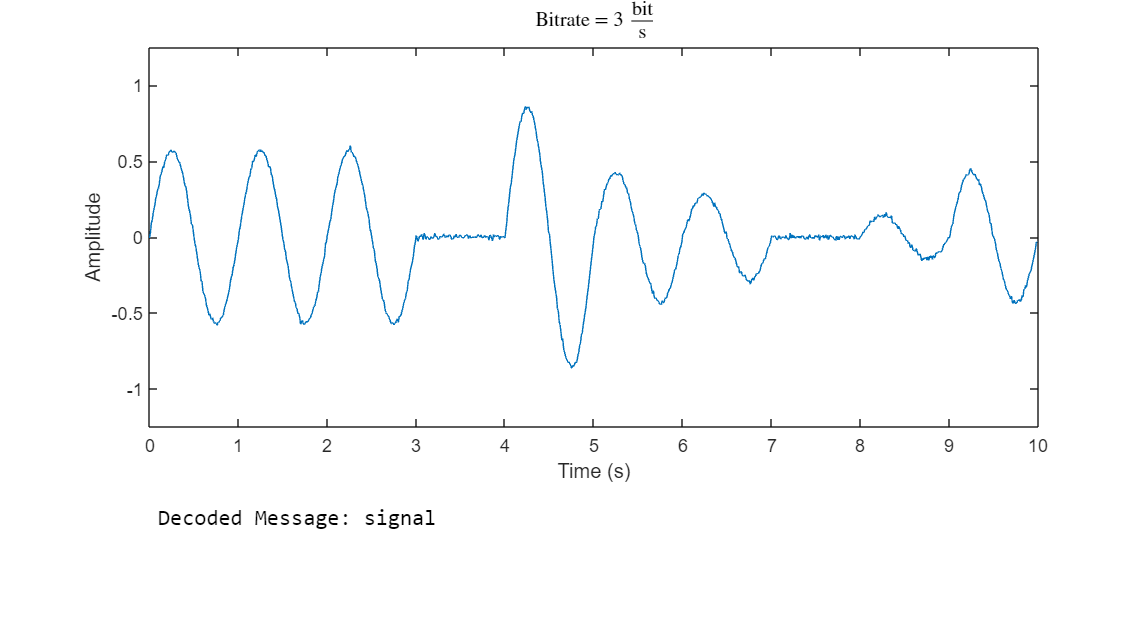

message = 'signal';
fs = 100;
std = 0.01;
codedMessage = cell(1,3);
noisyMessage = cell(1,3);

for bitrate = 1:3
    codedMessage{bitrate} = coding_amp(message, bitrate, mapset);
    noise = std * randn(1, length(codedMessage{bitrate}));
    noisyMessage{bitrate} = codedMessage{bitrate} + noise;
    t = 0:1/fs:(length(noisyMessage{bitrate})/fs) - 1/fs;
    figure('Position',[0,0,900,500]);
    subplot(4,1,1:3)
    plot(t, noisyMessage{bitrate})
    title("Bitrate = " + bitrate + " $\frac{\mathrm{bit}}{\mathrm{s}}$",'Interpreter','latex')
    xlabel("Time (s)")
    ylabel("Amplitude")
    ylim([-1.25, 1.25])
    decodedMessage = decoding_amp(noisyMessage{bitrate}, bitrate, mapset);
    subplot(4,1,4)
    axis off
    text(0.01, 0.5, sprintf('Decoded Message: %s', decodedMessage), 'FontName','consolas', 'FontSize', 12)
end

#### 1 - 7)

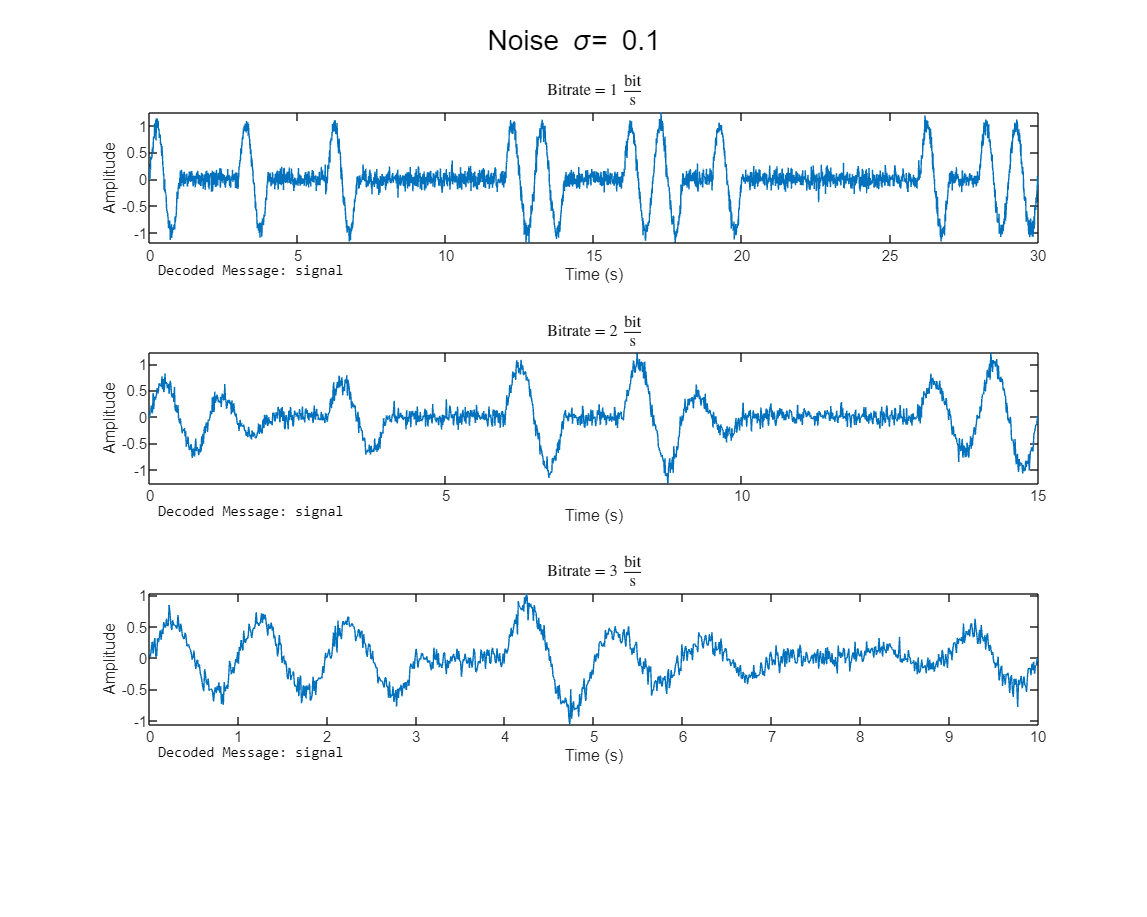

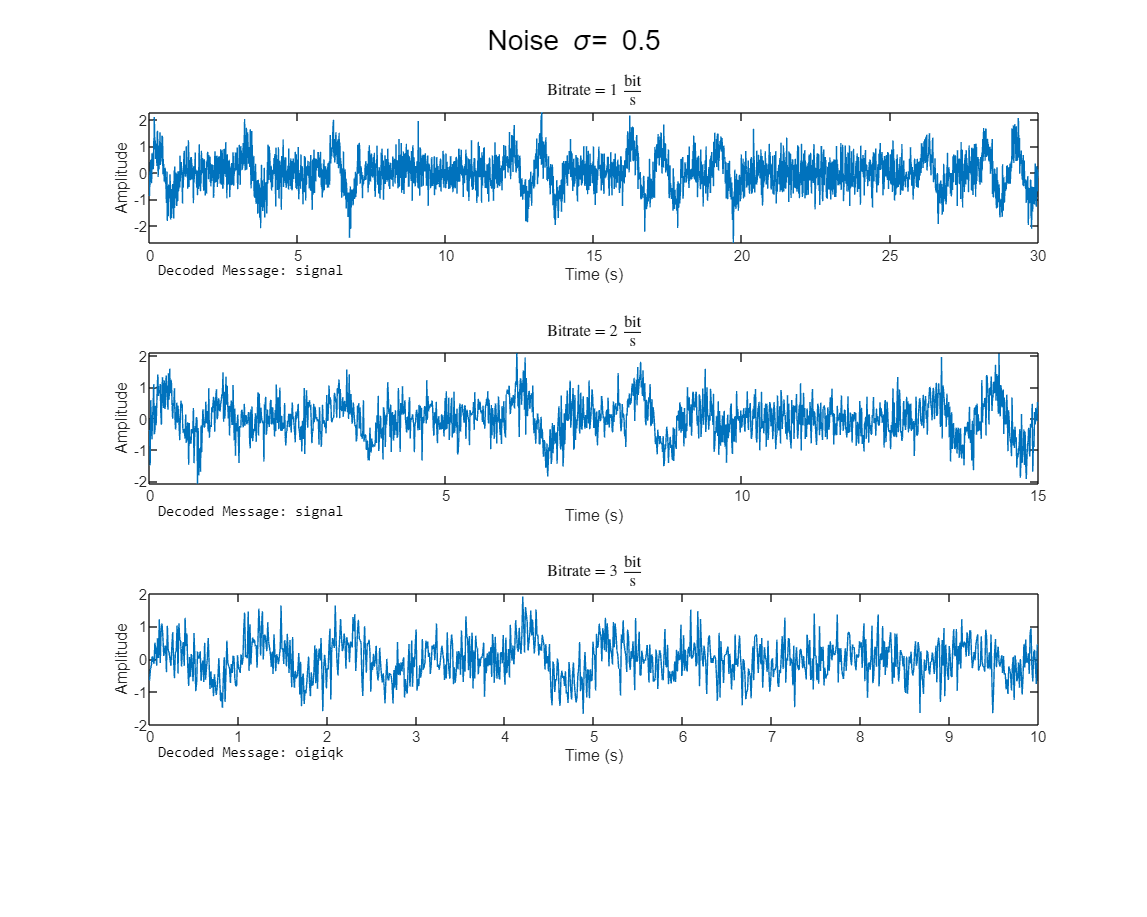

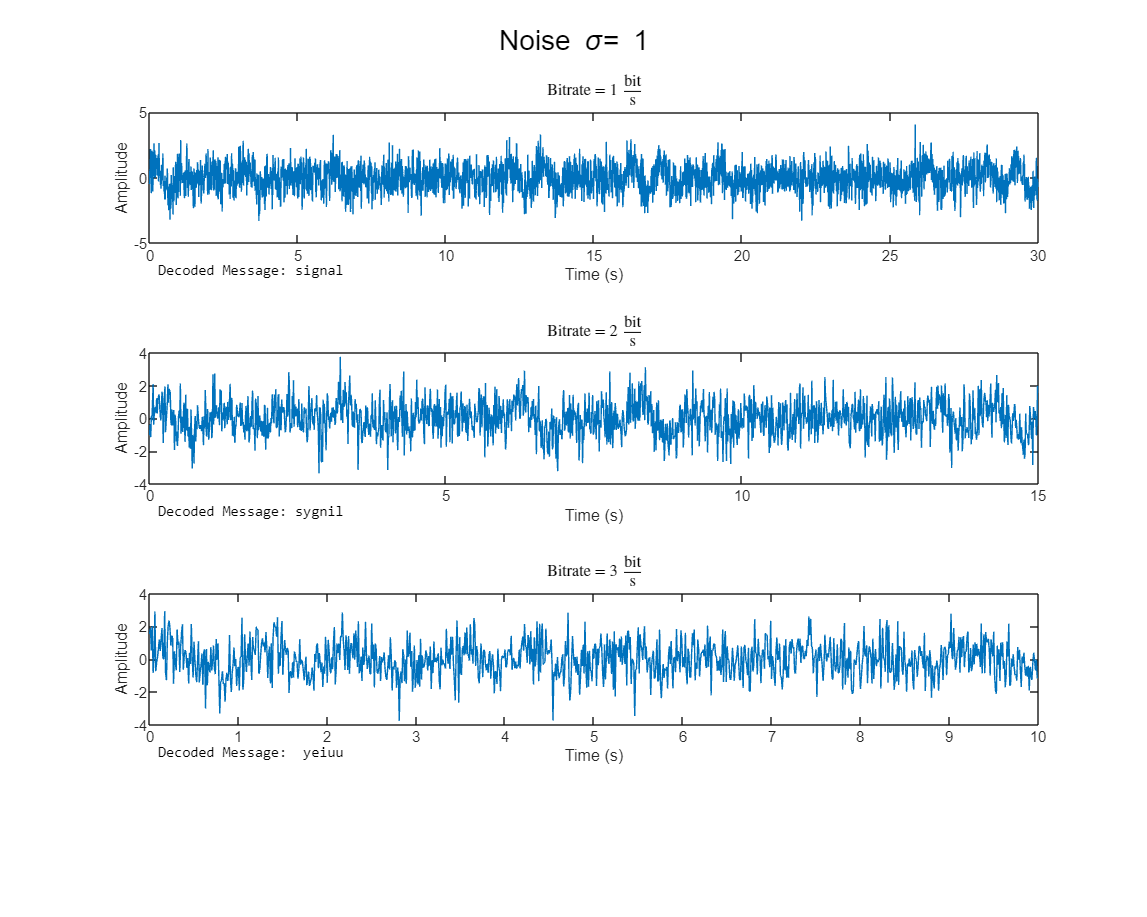

message = 'signal';
fs = 100;
codedMessage = cell(1,3);
noisyMessage = cell(1,3);
stds = [0.1, 0.5, 1];
for std = stds
    figure('Position',[0, 0, 1500, 1200]);
    sgtitle("Noise \sigma= " + std);
    for bitrate = 1:3
        codedMessage{bitrate} = coding_amp(message, bitrate, mapset);
        noise = std * randn(1, length(codedMessage{bitrate}));
        noisyMessage{bitrate} = codedMessage{bitrate} + noise;
        t = 0:1/fs:(length(noisyMessage{bitrate})/fs) - 1/fs;
        subplot(15,1,((bitrate-1)*5 + 1):((bitrate-1)*5 + 3));
        plot(t, noisyMessage{bitrate})
        title("Bitrate = " + bitrate + " $\frac{\mathrm{bit}}{\mathrm{s}}$",'Interpreter','latex')
        xlabel("Time (s)"); ylabel("Amplitude");
        decodedMessage = decoding_amp(noisyMessage{bitrate}, bitrate, mapset);
        subplot(15,1,(bitrate-1)*5 + 4);
        axis off
        text(0.01, 0.5, sprintf('Decoded Message: %s', decodedMessage), 'FontName','consolas', 'FontSize', 8)
    end
end

### Functions

function binarizedMessage = message2binary(message, mapset)
    binarizedMessage = '';
    for charInMessage = message
        found = false;
        for charInMapSet = mapset
            if charInMessage == charInMapSet{1};
                binarizedMessage = [binarizedMessage, charInMapSet{2}];
                found = true;
                break;
            end
        end
        if ~found
            fprintf('Character "%c" not found in mapset. Skipping...\n', charInMessage);
        end
    end
end

function codedMessage = coding_amp(message ,bitrate, mapset)
while(mod(length(message), bitrate) ~= 0)
    message = [message, ';'];
end
fs = 100;
codedMessage = [];
t = 0:(1/fs):1-(1/fs);
binarizedMessage = message2binary(message, mapset);
for i = 1:bitrate:length(binarizedMessage)
    bit = binarizedMessage(i: i+bitrate-1);
    alpha = bin2dec(bit) / (2^bitrate -1);
    signal = alpha*sin(2*pi*t);
    codedMessage = [codedMessage, signal];
end
end

function correlation = corr(a, b)
correlation = 0.01 * dot(a, b);
    correlation = max(0, correlation);
    correlation = min(correlation, 1);
end

function character = getCharacter(binary, mapset)
    for char = mapset
        if char{2} == binary
            character = char{1};
            break;
        end
    end 
end

function decodedMessage = decoding_amp(codedMessage, bitrate, mapset)
fs = 100;
t = 0:1/fs:1-1/fs;
binarizedMessage = '';
decodedMessage = '';
template = 2 * sin (2 * pi * t);
for i = 1:length(codedMessage)/fs
    segment = codedMessage((i-1) * fs + 1: i * fs);
    correlation = corr(segment, template);
    for j = 0:(2^bitrate - 1)
        if max(0, j/(2^bitrate-1) - (0.5/(2^bitrate-1))) <= correlation && correlation <= min(1, j/(2^bitrate-1) + (0.5/(2^bitrate-1)))
            binarizedMessage = [binarizedMessage, dec2bin(j,bitrate)];
            break;
        end
    end
end
for i = 1:5:length(binarizedMessage)
    character = getCharacter(binarizedMessage(i:i+4), mapset);
    decodedMessage = [decodedMessage, character];
end
end